## Esercizio 1

Si ricavino le matrici del modello di un carrello elevatore a trazione elettrica in modalità di frenatura:


$$m\ddot{p}+b\dot{p}+\frac{k_m^2}{R_a+R_f}\dot{p}=0\\
x_1=p;\ x_2=\dot{p}\\$$


### Soluzione

Inanzitutto scegliamo la variabile di stato $x=p \Rightarrow \dot{x}=\dot{p}$

Poi:

syms m km Ra Rf b;
syms x1 x2 x1dot x2dot u y t;


$$x=\pmatrix{x_1 \cr x_2}$$


x=[x1;x2];


$$\dot{x}=\pmatrix{\dot{x_1} \cr \dot{x_2}}$$


xdot=[x1dot;x2dot];


$$\begin{cases}
\dot{x_1}=x_2\\
m\dot{x_2}+bx_2+\frac{k_m^2}{R_a+R_f}x_2=0
\end{cases}$$


(l'equazione $\dot{x_1}=x_2$ la otteniamo TODO)

eqns = [x1dot==x2; m*x2dot+b*x2+(km^2/(Ra+Rf))*x2==0];

Risolviamo il sistema di equazioni per $\dot{x_1}$ e $\dot{x_2}$ usando solve

[x1dot,x2dot]=solve(eqns,xdot);
xdot = [x1dot;x2dot];

Ricaviamo le matrici $A$ e $B$ usando equationsToMatrix

[A,Bu]=equationsToMatrix(xdot,x)

$$A = \left(\begin{array}{cc} 0 & 1\\ 0 & -\frac{{\mathrm{km}}^{2}+\mathrm{Ra}\,b+\mathrm{Rf}\,b}{m\,\left(\mathrm{Ra}+\mathrm{Rf}\right)} \end{array}\right)$$

$$Bu = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

B=-Bu/u

$$B = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

## Esercizio 2

Dati i seguenti valori numerici:


$$m=1000;\ b=100;\ R_a=10;\ R_f=90;\ k_m=300$$


Si determini  lo spazio percorso e la velocità raggiunta in 12 secondi dal veicolo (ovvero $x(t=12)$) in modalità di frenata, considerando una velocità iniziale di $5\frac{m}{s}$, vale a dire:


$$x(0)=\pmatrix{0\cr 5}$$


Ricaviamo la matrice $A$ in forma numerica


$$m=1000;\ b=100;\ R_a=10;\ R_f=90;\ k_m=300$$


m=1000;
b=100;
Ra=10;
Rf=90;
km=300;

A=subs(A);

Ricaviamo l'esponenziale di matrice $e^{At}$ in forma simbolica

eAt=expm(A*t);

Risolviamo ora l'esercizio in forma numerica


$$x(0)=\pmatrix{0\cr 5}$$


x0=[0;5];


$$t_{\text{finale}}=12$$


tf=12;


$$x(t_{\text{finale}})=x(12)=e^{12A}x(0)$$


x12=expm(A*tf)*x0

$$x12 = \left(\begin{array}{c} 5-5\,{\mathrm{e}}^{-12}\\ 5\,{\mathrm{e}}^{-12} \end{array}\right)$$

Approssimazione numerica:

var = vpa(x12)

$$var = \left(\begin{array}{c} 4.9999692789382333589512065884591\\ 0.000030721061766641048793411540894028 \end{array}\right)$$

Grafico di funzioni simboliche:

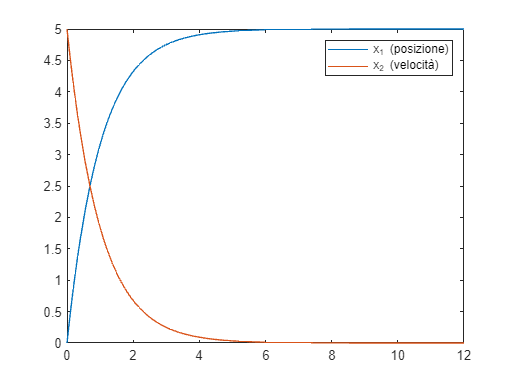

fplot(eAt*x0, [0,12])
legend("x_1 (posizione)", "x_2 (velocità)")